% IOE 511/MATH 562, University of Michigan
% Code written by: Minghao Chen

% Script to run code

% close all figures, clear all variables from workspace and clear command
% window
% close all
clear all
clc

format long

tic

rng(0);

% set problem (minimal requirement: name of problem)
problem.name = "quartic_2";
problem.x0 = [cos(70);sin(70);cos(70);sin(70)];
problem.n = length(problem.x0);
problem.memory = 5;


% set method (minimal requirement: name of method)
method.name = 'GradientDescent'; % option: GradientDescent, Newton, BFGS, L-BFGS
method.options.step_type = 'Backtracking'; % option: Constant, Backtracking, Modified Backtracking (Newton)
%method.options.constant_step_size = 1e-3;

% set options   
options.term_tol = 1e-6;
options.max_iterations = 1e4;
fstar = 1;

% run method and return x^* and f^*
[x,f,k,delta,norm_g] = optSolver(problem,method,options);

% output
timeElapsed = toc; 
fprintf('%15s %15s %15s %15s','Iteration','Func val','Norm Grad','CPU Seconds');

      Iteration        Func val       Norm Grad     CPU Seconds

fprintf('%15d %15.4e %15.4e %15.4f',k,f,norm_g,timeElapsed); 

              5      1.0307e-03      2.1112e-01          0.0536

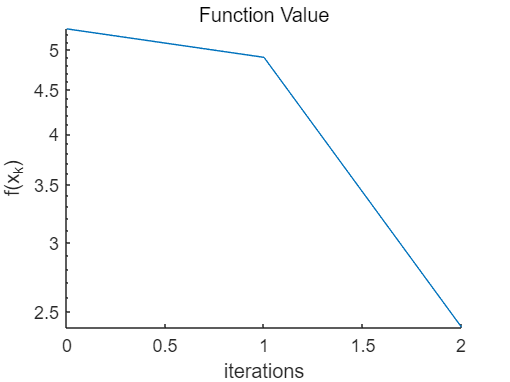


% plot the difference between fx and fx v.s. iterations^*
figure(1)
plot(0:k,log10(delta(1:k+1)));
title("Function Value");
xlabel("iterations");
ylabel("f(x_k)");
box off
hold on
set(gca,'Yscale','log') % log scale